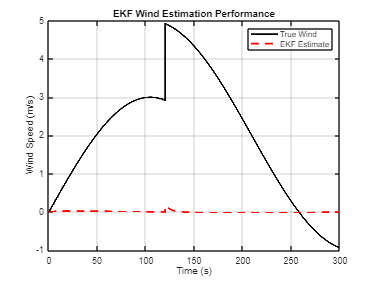

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% UAV AUTONOMOUS FLIGHT UNDER ENVIRONMENTAL UNCERTAINTY
%
% Wind-Aware | Energy-Optimal | Adaptive Control | EKF Estimation
%
% M.Tech Project – Research-Grade Simulation Prototype
%
% References:
% 1. Beard & McLain – Small Unmanned Aircraft
% 2. Langelaan – Wind Estimation for UAVs (AIAA)
% 3. Stevens & Lewis – Aircraft Control & Simulation
% 4. Bryson & Ho – Applied Optimal Control
% 5. Ioannou & Sun – Robust Adaptive Control
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear; clc; close all;
rng(1);   % Reproducibility

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% SIMULATION SETUP
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

dt = 0.05;                 % Time step (s)
T  = 300;                  % Total simulation time (s)
t  = 0:dt:T;               % Time vector
N  = length(t);            % Number of time steps

rho = 1.225;               % Air density (kg/m^3)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% UAV PARAMETERS (Fixed-Wing UAV – Beard & McLain Class)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

m_nominal = 13.5;          % Nominal mass (kg)
payload   = 3.0;           % Payload mass (kg)

S   = 0.55;                % Wing area (m^2)
CD0 = 0.028;               % Zero-lift drag coefficient
k   = 0.045;               % Induced drag factor

Va_star = 18;              % Minimum power airspeed (m/s)
Va_min  = 14;              % Minimum allowable airspeed (m/s)
Va_max  = 28;              % Maximum allowable airspeed (m/s)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ENVIRONMENT (UNKNOWN TO AUTONOMY SYSTEM)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% True wind profile (positive = headwind)
wind_true = 3*sin(0.015*t) + 2*(t > 120);

% Payload release event
payload_released = t >= 150;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% TRUE VEHICLE STATES (GROUND TRUTH)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

x  = zeros(1,N);           % Longitudinal position (m)
y  = zeros(1,N);           % Lateral deviation (m)
Vg = zeros(1,N);           % Ground speed (m/s)
Va = zeros(1,N);           % Airspeed (m/s)

Vg(1) = Va_star;           % Initial trim condition

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% EXTENDED KALMAN FILTER (EKF) INITIALIZATION
% States: [ Ground Speed ; Wind Speed ; Mass Bias ]
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

xhat = [Va_star; 0; 0];    % Initial state estimate
P    = diag([4 4 1]);      % Initial covariance

Q = diag([0.1 0.01 0.001]); % Process noise covariance
R = 2.0;                   % Airspeed measurement noise variance

wind_est = zeros(1,N);    % Estimated wind
mass_est = zeros(1,N);    % Estimated mass

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% DATA LOGS FOR ANALYSIS
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Va_cmd_log = zeros(1,N);

Thrust_fixed = zeros(1,N);
Thrust_adapt = zeros(1,N);

Power_fixed  = zeros(1,N);
Power_adapt  = zeros(1,N);

Energy_fixed = zeros(1,N);
Energy_adapt = zeros(1,N);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% MAIN AUTONOMOUS FLIGHT SIMULATION LOOP
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k = 1:N-1

    %----------------------------------------------------------
    % TRUE MASS (Payload Drop)
    %----------------------------------------------------------
    if payload_released(k)
        m_true = m_nominal - payload;
    else
        m_true = m_nominal;
    end

    %----------------------------------------------------------
    % TRUE AIRSPEED (Wind-Relative)
    %----------------------------------------------------------
    Va(k) = Vg(k) - wind_true(k);

    %----------------------------------------------------------
    % EKF PREDICTION STEP
    %----------------------------------------------------------
    xhat = xhat;
    P = P + Q;

    %----------------------------------------------------------
    % EKF UPDATE STEP (Airspeed Measurement)
    %----------------------------------------------------------
    z = Va(k);                      % Measured airspeed
    h = xhat(1) - xhat(2);          % Measurement model
    H = [1 -1 0];                   % Measurement Jacobian

    K = P*H'/(H*P*H' + R);           % Kalman gain
    xhat = xhat + K*(z - h);         % State update
    P = (eye(3) - K*H)*P;            % Covariance update

    wind_hat = xhat(2);
    m_hat    = m_nominal + xhat(3);

    wind_est(k) = wind_hat;
    mass_est(k) = m_hat;

    %----------------------------------------------------------
    % ENERGY-OPTIMAL GUIDANCE LAW
    %----------------------------------------------------------
    Va_cmd = Va_star + 0.6*max(wind_hat,0);
    Va_cmd = min(max(Va_cmd,Va_min),Va_max);
    Va_cmd_log(k) = Va_cmd;

    %----------------------------------------------------------
    % AERODYNAMIC DRAG MODEL
    %----------------------------------------------------------
    q = 0.5*rho*Va(k)^2;             % Dynamic pressure
    Drag = q*S*(CD0 + k*0.6^2);

    %----------------------------------------------------------
    % CONTROL LAWS (Fixed vs Adaptive)
    %----------------------------------------------------------
    Kp_fixed = 2.2;
    Kp_adapt = Kp_fixed*(m_nominal/max(m_hat,1));

    Thrust_fixed(k) = Drag + Kp_fixed*(Va_cmd - Va(k));
    Thrust_adapt(k) = Drag + Kp_adapt*(Va_cmd - Va(k));

    %----------------------------------------------------------
    % VEHICLE DYNAMICS UPDATE (Adaptive Control Applied)
    %----------------------------------------------------------
    ax = (Thrust_adapt(k) - Drag)/m_true;
    Vg(k+1) = Vg(k) + ax*dt;

    x(k+1) = x(k) + Vg(k)*dt;
    y(k+1) = 30*sin(0.01*t(k));      % Lateral motion (for 3D view)

    %----------------------------------------------------------
    % ENERGY ACCOUNTING
    %----------------------------------------------------------
    Power_fixed(k) = Thrust_fixed(k)*Va(k);
    Power_adapt(k) = Thrust_adapt(k)*Va(k);

    Energy_fixed(k+1) = Energy_fixed(k) + Power_fixed(k)*dt;
    Energy_adapt(k+1) = Energy_adapt(k) + Power_adapt(k)*dt;
end

Va(end) = Vg(end) - wind_true(end);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% VISUALIZATION & RESULTS
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Wind estimation performance
figure;
plot(t, wind_true,'k','LineWidth',2); hold on;
plot(t, wind_est,'r--','LineWidth',2);
xlabel('Time (s)');
ylabel('Wind Speed (m/s)');
legend('True Wind','EKF Estimate');
title('EKF Wind Estimation Performance');
grid on;

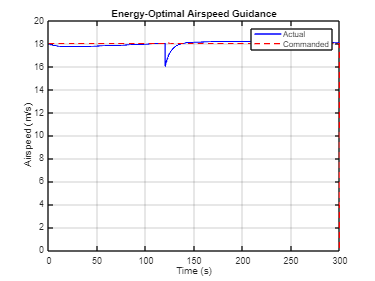


% Airspeed tracking
figure;
plot(t, Va,'b','LineWidth',1.5); hold on;
plot(t, Va_cmd_log,'r--','LineWidth',1.5);
xlabel('Time (s)');
ylabel('Airspeed (m/s)');
legend('Actual','Commanded');
title('Energy-Optimal Airspeed Guidance');
grid on;

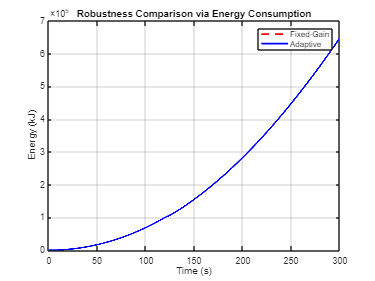


% Energy comparison
figure;
plot(t, Energy_fixed/1000,'r--','LineWidth',2); hold on;
plot(t, Energy_adapt/1000,'b','LineWidth',2);
xlabel('Time (s)');
ylabel('Energy (kJ)');
legend('Fixed-Gain','Adaptive');
title('Robustness Comparison via Energy Consumption');
grid on;

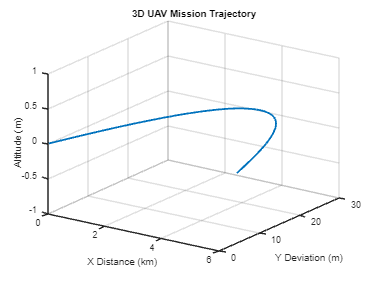


% 3D trajectory visualization
figure;
plot3(x/1000,y,zeros(size(x)),'LineWidth',2);
xlabel('X Distance (km)');
ylabel('Y Deviation (m)');
zlabel('Altitude (m)');
title('3D UAV Mission Trajectory');
grid on;
view(35,25);


% Summary table (defense-ready)
Results = table( ...
    Energy_fixed(end)/1000, ...
    Energy_adapt(end)/1000, ...
    max(abs(wind_true - wind_est)), ...
    'VariableNames', ...
    {'Energy_Fixed_kJ','Energy_Adaptive_kJ','Max_Wind_Est_Error_mps'} );

disp(Results);

    Energy_Fixed_kJ    Energy_Adaptive_kJ    Max_Wind_Est_Error_mps
    _______________    __________________    ______________________

       6.46e+05             6.46e+05                 4.8834        

